# Upsampling

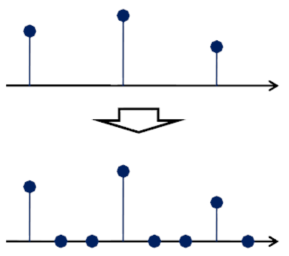

close all;
clear all;
clc;

#### Signal Definition

len=1;%[s]
fs=8;%[Hz]
Ts=1/fs;%[s]


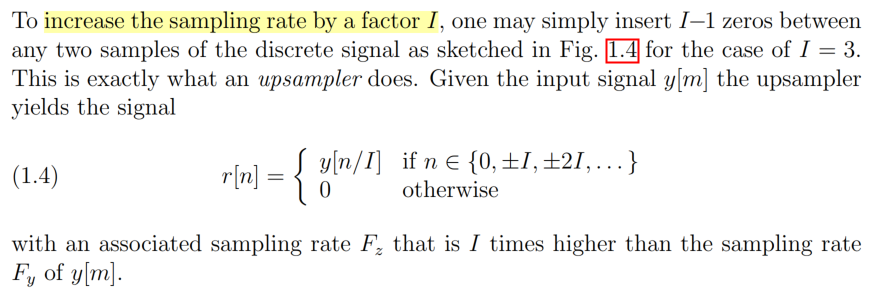

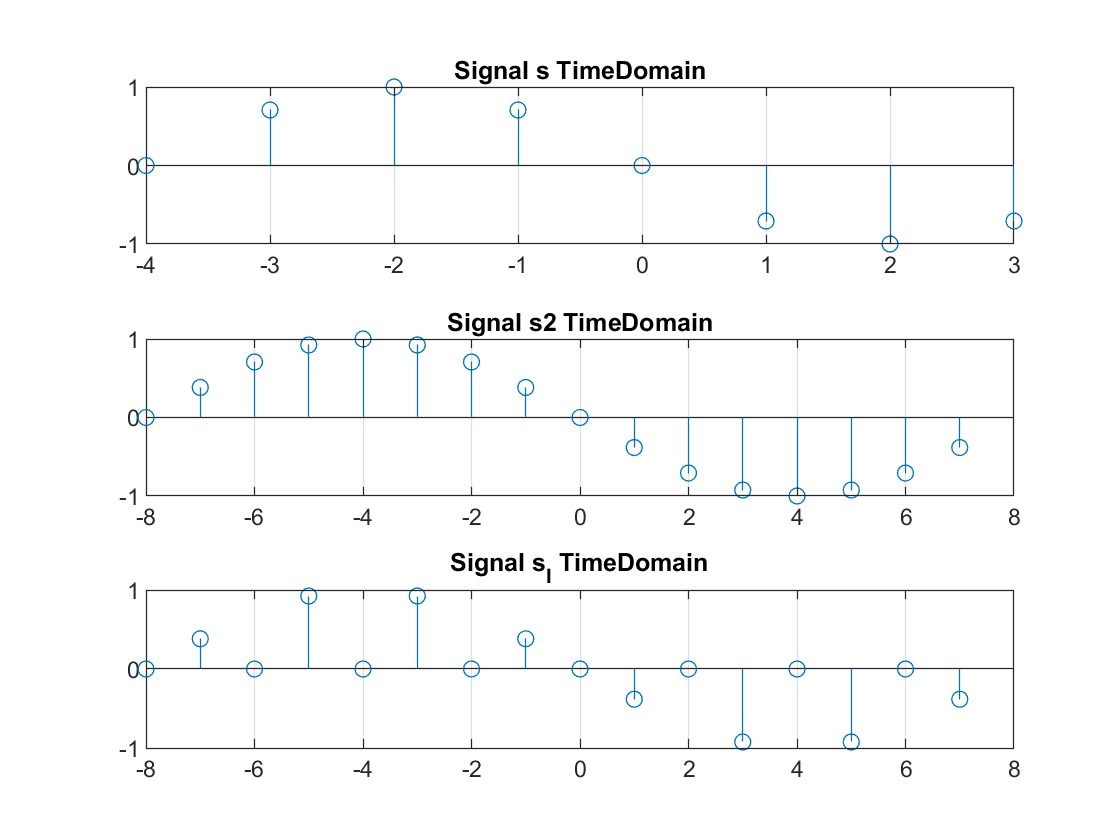

I=2;
Tz=1/(I*fs);
n=[0:Ts:len-Ts];
n_I=[0:Tz:len-Tz];

f=1;
w=2*pi*f;
s=exp(i*w*n);
s_I=exp(i*w*n_I);
s2=s_I;

%do Upsampling
for ind=1:length(s_I)
    if mod(ind,2)
        s_I(ind)=0;
    end
end

figure;
subplot(3,1,1)
stem((-length(s)/2:1:length(s)/2-1),imag(s))
grid on;
title('Signal s TimeDomain')
subplot(3,1,2)
stem((-length(s2)/2:1:length(s2)/2-1),imag(s2))
grid on;
title('Signal s2 TimeDomain')
subplot(3,1,3)
stem((-length(s_I)/2:1:length(s_I)/2-1),imag(s_I))
grid on;
title('Signal s_I TimeDomain')

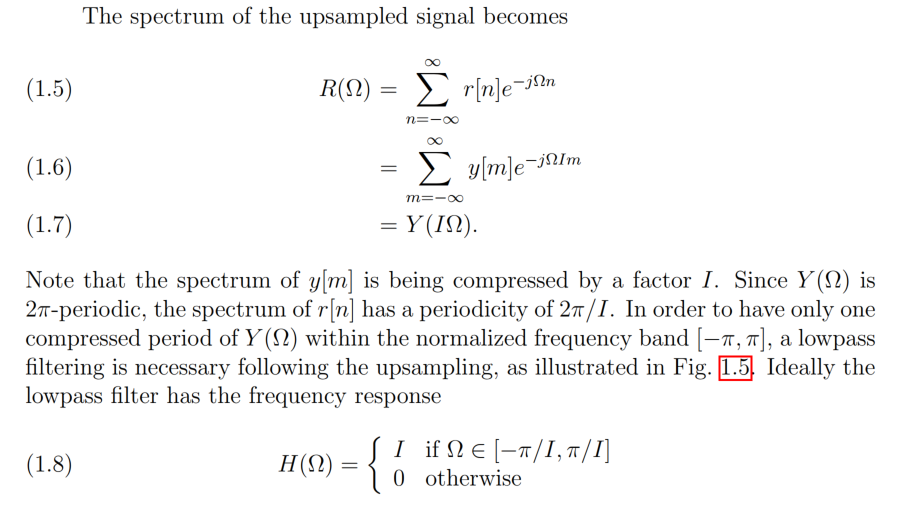

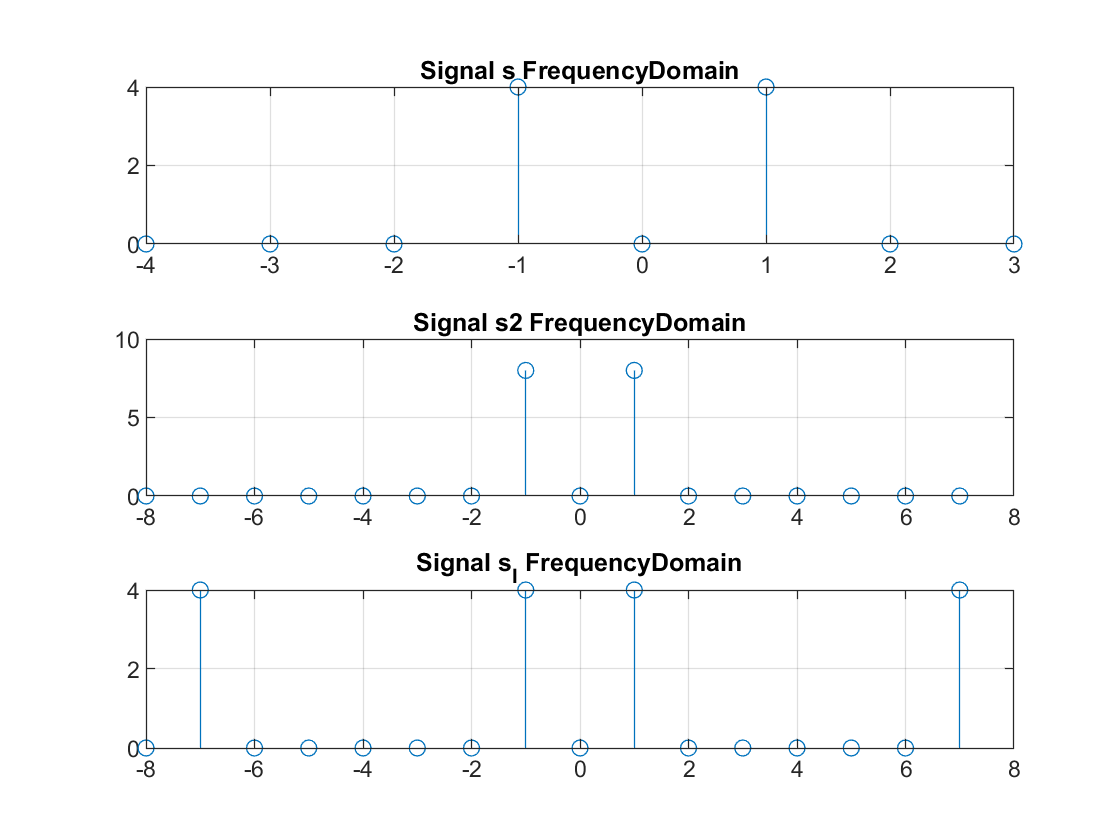

figure;
subplot(3,1,1)
stem((-length(s)/2:1:length(s)/2-1),fftshift(abs(fft(imag(s)))));
grid on;
title('Signal s FrequencyDomain')
subplot(3,1,2)
stem((-length(s2)/2:1:length(s2)/2-1),fftshift(abs(fft(imag(s2)))));
grid on;
title('Signal s2 FrequencyDomain')
subplot(3,1,3)
stem((-length(s_I)/2:1:length(s_I)/2-1),fftshift(abs(fft(imag(s_I)))));
grid on;
title('Signal s_I FrequencyDomain')

Desmos: [https://www.desmos.com/calculator/bgnqshhz3z?lang=de](https://www.desmos.com/calculator/bgnqshhz3z?lang=de)

#### Unit Circle: 

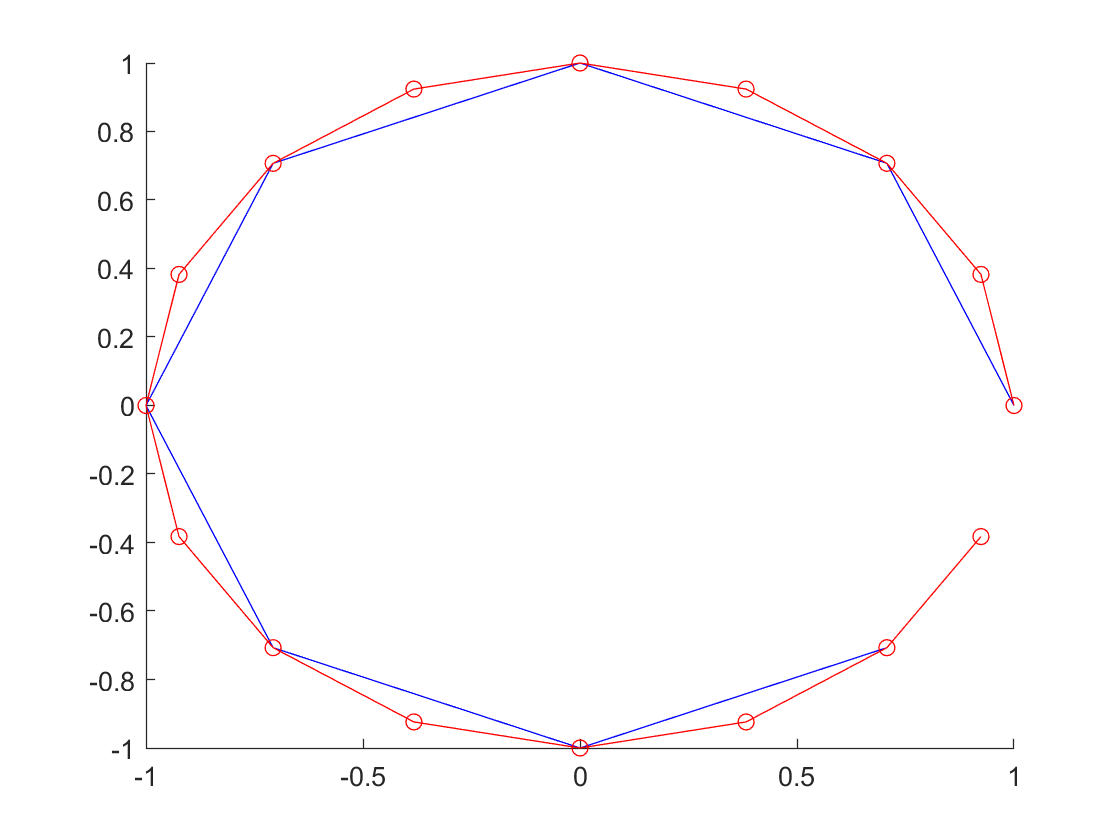

figure;
hold on;
plot(real(s),imag(s),'-bo');
plot(real(s2),imag(s2),'-ro');

plot(real(s_I),imag(s_I),'-go');

Error using plot
Unrecognized property none for class Line.

grid on;
hold off;
title('Signals Unitcircle, y-Im, x-re')

#### Redefenition of s_I: 

s_I2=exp(i*w*n_I*2);
s_I3=exp(i*w*n_I*0.5);
%do Upsampling
for ind=1:length(s_I)
    if mod(ind,2)
        s_I2(ind)=0;
        s_I3(ind)=0;
    end
end
figure;
hold on;
plot(real(s_I2),imag(s_I2),'-ro');
plot(real(s_I3),imag(s_I3),'-bo');
hold off; 
grid on;
title('Signals Unitcircle different f, y-Im, x-re')

#### Questions:

- where does this extra frequency come from in my S_I spectrum

- Why does my Unitcircle look like that? die linien gehen immerwieder zu 0 !!!!

- was heist compress? haben wir mehr oder weniger frequenzen ?